## tarPos生成

close all;


clear;
azSeg = 12;
elSeg = 6;
maxTrials = 50;
degArr = zeros(maxTrials,4); % 1=tar_az, 2=tar_el, 3=end_az, 4=end_el
tmpDist = zeros(maxTrials,1);

isOutOfView = 0;
% 1つ前の球との位置差(cos(az_diff)+cos(el_diff))
diffPrevPost = 0;
% 90° = 合計が1以上違う、120° = 合計が 1 + 0.5以上違う
diffThdCome = 1.5;
diffThdTrans = 1.732;
thdDeg = 45;
% -180--180
degArr(1,1) = 180/azSeg * randi([-azSeg, azSeg],1);
% -90--90
degArr(1,2) = 90/(elSeg) * randi([-elSeg, elSeg],1);


radius = 10;
tarFileName=[
    "Vision_come";
    "Haptic_come";
    "Vis_Hap_come";
    "None_come";
    "Vision_trans";
    "Haptic_trans";
    "Vis_Hap_trans";
    "None_trans"
    ];

for cond = 1:8
    % ターゲットの出現位置の決定
    for i=2:size(degArr,1)
        % 1つ前の仰角と方位角より一定値以上差を離す（連続して視界内に入らないようにするため）
        while isOutOfView == 0
            % ランダムで方位角と仰角を生成
            tmpAz = 180/azSeg * randi([-azSeg, azSeg],1);
            tmpEl = 90/elSeg * randi([-elSeg, elSeg],1);
            preAz = degArr(i-1,1);
            preEl = degArr(i-1,2);
            azPost = cos(deg2rad(tmpAz));
            azPrev = cos(deg2rad(degArr(i-1,1)));
            elPost = cos(deg2rad(tmpEl));
            elPrev = cos(deg2rad(degArr(i-1,2)));
            diffPrevPost = abs(azPost-azPrev) + abs(elPost-elPrev);
            %  1. post pre 両方の絶対値がthdDeg以上の時はazimに関わらず棄却（必ず見える）
            if (tmpEl <= -thdDeg && preEl <= -thdDeg)||(tmpEl >= thdDeg && preEl >= thdDeg)
                isOutOfView = 0;
                %  2. false when elev and azim is lower than set value
            elseif diffPrevPost <= diffThdCome
                isOutOfView = 0;
            else
                isOutOfView = 1;
            end
        end
        degArr(i,1)=tmpAz;
        degArr(i,2)=tmpEl;
        isOutOfView=0;

    end

    % endPoleの位置は一定の距離以上離す
    isEndPoleOkay = 0;
    enableDist = 8;
    % endPoleの出現位置の決定
    for i=1:size(degArr,1)
        while isEndPoleOkay == 0
            % ランダムで方位角と仰角を生成
            tmpAz = 180/azSeg * randi([-azSeg, azSeg],1);
            tmpEl = 90/elSeg * randi([-elSeg, elSeg],1);
            tarAz = degArr(i,1);
            tarEl = degArr(i,2);
            [p1,p2,p3] = sph2cart(deg2rad(tmpAz),deg2rad(tmpEl),radius);
            [o1,o2,o3] = sph2cart(deg2rad(tarAz),deg2rad(tarEl),radius);
            tmpDist(i,1) = norm([p1,p2,p3] - [o1,o2,o3]);

            if i ~= size(degArr,1)
                %  endPoleと次のtarPosが同時に視界に入らないようにする
                postAz = degArr(i+1,1);
                postEl = degArr(i+1,2);
                azPost = cos(deg2rad(postAz));
                azPrev = cos(deg2rad(tmpAz));
                elPost = cos(deg2rad(postEl));
                elPrev = cos(deg2rad(tmpEl));
                diffPrevPost = abs(azPost-azPrev) + abs(elPost-elPrev);
            end

            % endPoleの位置はtarPos一定の距離以上離す
            if tmpDist(i,1) >= enableDist
                % except for last pos
                if i ~= size(degArr,1)
                    %  1. post pre 両方の絶対値がthdDeg以上の時はazimに関わらず棄却（必ず見える）
                    if (tmpEl <= -thdDeg && postEl <= -thdDeg)||(tmpEl >= thdDeg && postEl >= thdDeg)
                        isEndPoleOkay = 0;
                        %  2. false when elev and azim is lower than set value
                    elseif diffPrevPost <= diffThdCome
                        isEndPoleOkay = 0;
                    else
                        isEndPoleOkay = 1;
                    end
                else
                    isEndPoleOkay = 1;
                end

            end
        end
        degArr(i,3)=tmpAz;
        degArr(i,4)=tmpEl;
        isEndPoleOkay = 0;
    end

    % 直交座標に変換
    [x,y,z] = sph2cart(deg2rad(degArr(:,1)),deg2rad(degArr(:,2)),radius);
    tarPlot = [x y z];
    [x,y,z] = sph2cart(deg2rad(degArr(:,3)),deg2rad(degArr(:,4)),radius);
    endPlot = [x y z];

    % [x,y,z] = sph2cart(-pi/2,0,10)
    % Unity は座標系が違うので、y,z を入れ替え。
    outTar = [tarPlot(:,1) tarPlot(:,3) tarPlot(:,2)];
    outEnd = [endPlot(:,1) endPlot(:,3) endPlot(:,2)];

    fName = tarFileName{cond,1} + ".csv";
    fEndName = tarFileName{cond,1} + "_end.csv";
    writematrix(outTar,fName);
    writematrix(outEnd,fEndName);

end

## 出現位置描画

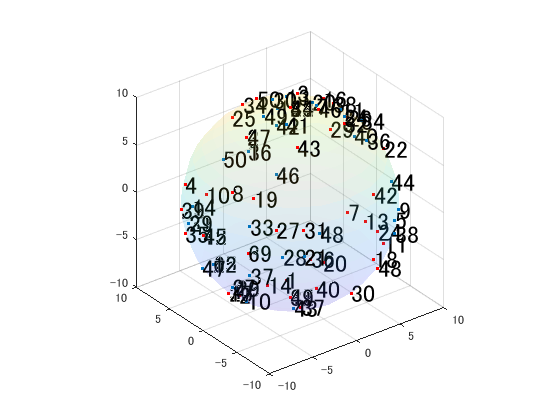

% 半径10の球をプロット
[X,Y,Z] = sphere;
r = 10;
X2 = X * r;
Y2 = Y * r;
Z2 = Z * r;
s = surf(X2,Y2,Z2,'FaceAlpha',0.1);
s.EdgeColor = 'none';
axis equal
set(gcf, 'visible', 'on');

hold on
plot3(tarPlot(:,1),tarPlot(:,2),tarPlot(:,3),'.');
for i=1:size(tarPlot,1)
    text(tarPlot(i,1),tarPlot(i,2),tarPlot(i,3),num2str(i),...
        "FontSize",18);
end

plot3(endPlot(:,1),endPlot(:,2),endPlot(:,3),'r.');
for i=1:size(endPlot,1)
    text(endPlot(i,1),endPlot(i,2),endPlot(i,3),num2str(i),...
        "FontSize",18);
end

## Archive



% % https://jp.mathworks.com/help/matlab/math/numbers-placed-randomly-within-volume-of-sphere.html?searchHighlight=%E7%90%83&s_tid=srchtitle_%25E7%2590%2583_1
% rng(0,'twister')
% % rvals = 2*rand(1000,1)-1;
% % elevation = asin(rvals);
% % azimuth = 2*pi*rand(1000,1);
%
%
% elDeg = 90; azDeg = 0;
%
% elevation = deg2rad(elDeg);
% azimuth = deg2rad(azDeg);
% [x,y,z] = sph2cart(azimuth,elevation,10);
% plot3(x,y,z,'.')
%
%
% % rand = 0~1
% randSignSeed(:,1) = rand(1000,1)-rand(1000,1);
% randSignSeed(:,2) = rand(1000,1)-rand(1000,1);
% signs = sign(randSignSeed);
%
% elDeg2 = 45*rand(1000,1).*signs(:,1) + elDeg;
% azDeg2 = sqrt(45^2-elDeg2.^2).*signs(:,2);
% % azDeg2 = 45*rand(1000,1).*signs(:,1);
% elevation2 = deg2rad(elDeg2);
% azimuth2 = deg2rad(azDeg2);
% [x2,y2,z2] = sph2cart(azimuth2,elevation2,10);
% plot3(x2,y2,z2,'.')
%
% set(gcf, 'visible', 'on')
% view([0 0])
% hold off
%
% p = [x y z];
% p2 = [x2 y2 z2];
%
% for i=1:size(p2,1)
%     dist(i,1) = norm(p(1,:)-p2(i,:));
%     %     dist(i,1) = norm([0 0 0]-p2(i,:));
% end


